## 创建50个城市点的数据集

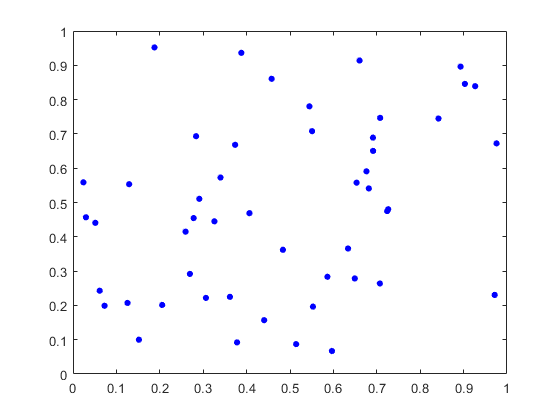

clc;
clf;
clear;

rng(3, 'twister');
cities = rand(2,50);
plot(cities(1, :), cities(2, :), 'b.', 'MarkerSize', 16, 'LineWidth',2);

% axis([-0.2, 1.2, -0.2, 1.2]);
save("50_cities.mat", "cities");

## 使用自己编写的模拟退火法进行求解

load("50_cities.mat")
temprature = 1e4;
temprature_min = 1e-6;
episodes = 20;
episode_length = 1e5;

multi_swap = 1;
trajectory_old = cities;
tic;
[trajectory_new, dist, temprature, exit_flag] = solveTSP(trajectory_old, temprature, temprature_min, episodes, episode_length, multi_swap);
toc;

历时 28.530351 秒。


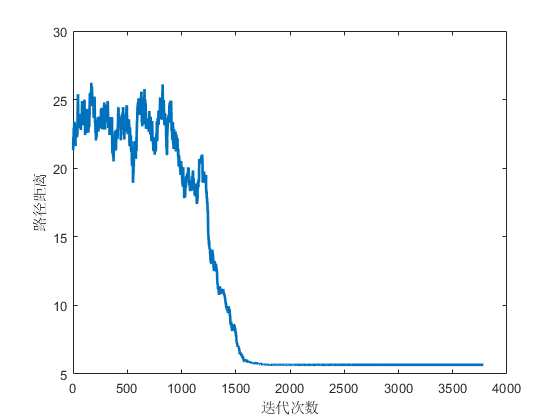

clf;
plot(dist, 'Linewidth', 2);
xlabel('迭代次数');
ylabel('路径距离');

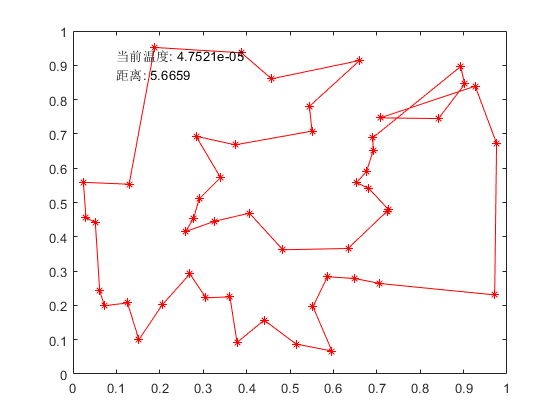


clf;
plot_trajectory(trajectory_new);
hold on;
text(0.1, 0.9, {['当前温度: ', num2str(temprature)];['距离: ', num2str(dist(end))]});

save("50_results.mat", "trajectory_new");


## 统计分析模拟退火法的收敛性质

load("50_cities.mat")
temperature_init = 1e4;
temprature_min = 1e-6;
episodes = 20;
episode_length = 1e4;
multi_swap = 1;

total = 1000;        % 统计100次实验

dists = [];                         % 记录每次实验中的路径变化情况
final_dists =zeros(1, total);       %记录最后求解得到的路径长度
final_temerature = zeros(1, total);
time_cost = zeros(1, total);
iteration = zeros(1, total);
for i=1:total
    temprature = temperature_init;
    trajectory_old = cities;
    tic;
    [~, dist, temprature, ~] = solveTSP(trajectory_old, temprature, temprature_min, episodes, episode_length, multi_swap);
    toc;
    fprintf('迭代次数：%d/1000',i);
    time_cost(i) = toc;
    final_dists(i) = dist(end);
    iteration(i) = length(dist);
    final_temerature(i) = temprature;
    
    % 添加一行新的迭代下降曲线
    if i==1
        dists = dist;
        continue;
    end
    
    len_old = size(dists, 2);
    len_new = size(dist, 2);
    if len_old < len_new
        dists(:, len_old:len_new) = repmat(dists(:, end),1, len_new-len_old+1);
    else
        dist(:, end:len_old) = dist(end);
    end
    dists = [dists; dist];
    
    
end

历时 2.937853 秒。


迭代次数：1/1000

历时 2.865133 秒。


迭代次数：2/1000

历时 2.850646 秒。


迭代次数：3/1000

历时 2.852608 秒。


迭代次数：4/1000

历时 2.828525 秒。


迭代次数：5/1000

历时 2.864801 秒。


迭代次数：6/1000

历时 2.835043 秒。


迭代次数：7/1000

历时 2.864767 秒。


迭代次数：8/1000

历时 2.878869 秒。


迭代次数：9/1000

历时 2.867168 秒。


迭代次数：10/1000

历时 2.841844 秒。


迭代次数：11/1000

历时 2.914287 秒。


迭代次数：12/1000

历时 4.478354 秒。


迭代次数：13/1000

历时 4.531612 秒。


迭代次数：14/1000

历时 4.002018 秒。


迭代次数：15/1000

历时 4.010110 秒。


迭代次数：16/1000

历时 4.020830 秒。


迭代次数：17/1000

历时 4.070097 秒。


迭代次数：18/1000

历时 4.023307 秒。


迭代次数：19/1000

历时 4.066273 秒。


迭代次数：20/1000

历时 4.122818 秒。


迭代次数：21/1000

历时 3.983131 秒。


迭代次数：22/1000

历时 4.019424 秒。


迭代次数：23/1000

历时 4.002830 秒。


迭代次数：24/1000

历时 3.997390 秒。


迭代次数：25/1000

历时 4.070271 秒。


迭代次数：26/1000

历时 4.009748 秒。


迭代次数：27/1000

历时 4.032986 秒。


迭代次数：28/1000

历时 4.035602 秒。


迭代次数：29/1000

历时 3.996487 秒。


迭代次数：30/1000

历时 3.982697 秒。


迭代次数：31/1000

历时 4.062200 秒。


迭代次数：32/1000

历时 4.073812 秒。


迭代次数：33/1000

历时 4.052233 秒。


迭代次数：34/1000

历时 4.045687 秒。


迭代次数：35/1000

历时 3.988112 秒。


迭代次数：36/1000

历时 3.969804 秒。


迭代次数：37/1000

历时 3.966294 秒。


迭代次数：38/1000

历时 3.982870 秒。


迭代次数：39/1000

历时 3.986202 秒。


迭代次数：40/1000

历时 3.962051 秒。


迭代次数：41/1000

历时 3.987031 秒。


迭代次数：42/1000

历时 3.978857 秒。


迭代次数：43/1000

历时 4.066208 秒。


迭代次数：44/1000

历时 3.945512 秒。


迭代次数：45/1000

历时 3.970993 秒。


迭代次数：46/1000

历时 4.029717 秒。


迭代次数：47/1000

历时 4.019118 秒。


迭代次数：48/1000

历时 3.972357 秒。


迭代次数：49/1000

历时 3.987971 秒。


迭代次数：50/1000

历时 4.001868 秒。


迭代次数：51/1000

历时 4.006641 秒。


迭代次数：52/1000

历时 3.985263 秒。


迭代次数：53/1000

历时 3.966608 秒。


迭代次数：54/1000

历时 4.101552 秒。


迭代次数：55/1000

历时 4.045882 秒。


迭代次数：56/1000

历时 3.987296 秒。


迭代次数：57/1000

历时 3.993961 秒。


迭代次数：58/1000

历时 3.951204 秒。


迭代次数：59/1000

历时 3.977020 秒。


迭代次数：60/1000

历时 4.002925 秒。


迭代次数：61/1000

历时 4.036773 秒。


迭代次数：62/1000

历时 3.970548 秒。


迭代次数：63/1000

历时 4.187652 秒。


迭代次数：64/1000

历时 4.005266 秒。


迭代次数：65/1000

历时 4.062728 秒。


迭代次数：66/1000

历时 3.972878 秒。


迭代次数：67/1000

历时 3.990631 秒。


迭代次数：68/1000

历时 3.974531 秒。


迭代次数：69/1000

历时 4.038527 秒。


迭代次数：70/1000

历时 3.991371 秒。


迭代次数：71/1000

历时 3.966508 秒。


迭代次数：72/1000

历时 3.999735 秒。


迭代次数：73/1000

历时 4.248881 秒。


迭代次数：74/1000

历时 4.188788 秒。


迭代次数：75/1000

历时 3.993875 秒。


迭代次数：76/1000

历时 4.078083 秒。


迭代次数：77/1000

历时 4.102963 秒。


迭代次数：78/1000

历时 4.029096 秒。


迭代次数：79/1000

历时 3.978301 秒。


迭代次数：80/1000

历时 3.993178 秒。


迭代次数：81/1000

历时 4.008880 秒。


迭代次数：82/1000

历时 4.153120 秒。


迭代次数：83/1000

历时 3.951895 秒。


迭代次数：84/1000

历时 4.118760 秒。


迭代次数：85/1000

历时 4.048346 秒。


迭代次数：86/1000

历时 4.099910 秒。


迭代次数：87/1000

历时 4.043185 秒。


迭代次数：88/1000

历时 4.036221 秒。


迭代次数：89/1000

历时 3.978405 秒。


迭代次数：90/1000

历时 4.011126 秒。


迭代次数：91/1000

历时 4.073795 秒。


迭代次数：92/1000

历时 3.981664 秒。


迭代次数：93/1000

历时 3.978109 秒。


迭代次数：94/1000

历时 3.964914 秒。


迭代次数：95/1000

历时 4.975518 秒。


迭代次数：96/1000

历时 4.354594 秒。


迭代次数：97/1000

历时 4.621389 秒。


迭代次数：98/1000

历时 4.493602 秒。


迭代次数：99/1000

历时 3.788538 秒。


迭代次数：100/1000

历时 3.978478 秒。


迭代次数：101/1000

历时 3.729693 秒。


迭代次数：102/1000

历时 3.783582 秒。


迭代次数：103/1000

历时 3.880984 秒。


迭代次数：104/1000

历时 3.718355 秒。


迭代次数：105/1000

历时 3.739032 秒。


迭代次数：106/1000

历时 3.964313 秒。


迭代次数：107/1000

历时 4.385556 秒。


迭代次数：108/1000

历时 3.859583 秒。


迭代次数：109/1000

历时 3.770231 秒。


迭代次数：110/1000

历时 3.709195 秒。


迭代次数：111/1000

历时 3.723479 秒。


迭代次数：112/1000

历时 3.715547 秒。


迭代次数：113/1000

历时 3.773315 秒。


迭代次数：114/1000

历时 3.739668 秒。


迭代次数：115/1000

历时 3.750005 秒。


迭代次数：116/1000

历时 3.764746 秒。


迭代次数：117/1000

历时 3.752881 秒。


迭代次数：118/1000

历时 3.770295 秒。


迭代次数：119/1000

历时 3.731798 秒。


迭代次数：120/1000

历时 3.711335 秒。


迭代次数：121/1000

历时 3.756224 秒。


迭代次数：122/1000

历时 3.809965 秒。


迭代次数：123/1000

历时 3.761034 秒。


迭代次数：124/1000

历时 3.756265 秒。


迭代次数：125/1000

历时 3.693057 秒。


迭代次数：126/1000

历时 3.716727 秒。


迭代次数：127/1000

历时 3.724015 秒。


迭代次数：128/1000

历时 3.753329 秒。


迭代次数：129/1000

历时 3.703138 秒。


迭代次数：130/1000

历时 3.747720 秒。


迭代次数：131/1000

历时 3.720472 秒。


迭代次数：132/1000

历时 3.695234 秒。


迭代次数：133/1000

历时 3.714481 秒。


迭代次数：134/1000

历时 3.736580 秒。


迭代次数：135/1000

历时 3.712082 秒。


迭代次数：136/1000

历时 3.714263 秒。


迭代次数：137/1000

历时 3.714799 秒。


迭代次数：138/1000

历时 3.718670 秒。


迭代次数：139/1000

历时 3.693191 秒。


迭代次数：140/1000

历时 3.729776 秒。


迭代次数：141/1000

历时 3.701354 秒。


迭代次数：142/1000

历时 3.754245 秒。


迭代次数：143/1000

历时 3.776109 秒。


迭代次数：144/1000

历时 3.725090 秒。


迭代次数：145/1000

历时 3.751006 秒。


迭代次数：146/1000

历时 3.781325 秒。


迭代次数：147/1000

历时 3.772712 秒。


迭代次数：148/1000

历时 3.733725 秒。


迭代次数：149/1000

历时 3.768220 秒。


迭代次数：150/1000

历时 3.767066 秒。


迭代次数：151/1000

历时 3.752234 秒。


迭代次数：152/1000

历时 3.711237 秒。


迭代次数：153/1000

历时 3.734041 秒。


迭代次数：154/1000

历时 4.131896 秒。


迭代次数：155/1000

历时 3.694633 秒。


迭代次数：156/1000

历时 3.707024 秒。


迭代次数：157/1000

历时 4.016019 秒。


迭代次数：158/1000

历时 3.876481 秒。


迭代次数：159/1000

历时 3.774428 秒。


迭代次数：160/1000

历时 3.691414 秒。


迭代次数：161/1000

历时 3.795595 秒。


迭代次数：162/1000

历时 3.760596 秒。


迭代次数：163/1000

历时 3.869108 秒。


迭代次数：164/1000

历时 3.731918 秒。


迭代次数：165/1000

历时 3.977217 秒。


迭代次数：166/1000

历时 4.535816 秒。


迭代次数：167/1000

历时 3.914000 秒。


迭代次数：168/1000

历时 3.903551 秒。


迭代次数：169/1000

历时 3.960899 秒。


迭代次数：170/1000

历时 3.908016 秒。


迭代次数：171/1000

历时 3.927528 秒。


迭代次数：172/1000

历时 3.987610 秒。


迭代次数：173/1000

历时 3.955509 秒。


迭代次数：174/1000

历时 3.899910 秒。


迭代次数：175/1000

历时 3.919238 秒。


迭代次数：176/1000

历时 3.980080 秒。


迭代次数：177/1000

历时 4.027798 秒。


迭代次数：178/1000

历时 3.954246 秒。


迭代次数：179/1000

历时 3.805757 秒。


迭代次数：180/1000

历时 3.754855 秒。


迭代次数：181/1000

历时 3.774626 秒。


迭代次数：182/1000

历时 3.751279 秒。


迭代次数：183/1000

历时 3.729278 秒。


迭代次数：184/1000

历时 3.746412 秒。


迭代次数：185/1000

历时 3.780094 秒。


迭代次数：186/1000

历时 3.729935 秒。


迭代次数：187/1000

历时 3.713504 秒。


迭代次数：188/1000

历时 3.775200 秒。


迭代次数：189/1000

历时 4.616014 秒。


迭代次数：190/1000

历时 3.719672 秒。


迭代次数：191/1000

历时 3.734616 秒。


迭代次数：192/1000

历时 4.180592 秒。


迭代次数：193/1000

历时 4.827849 秒。


迭代次数：194/1000

历时 4.680962 秒。


迭代次数：195/1000

历时 4.066301 秒。


迭代次数：196/1000

历时 3.729138 秒。


迭代次数：197/1000

历时 3.748784 秒。


迭代次数：198/1000

历时 4.257359 秒。


迭代次数：199/1000

历时 4.372504 秒。


迭代次数：200/1000

历时 4.134976 秒。


迭代次数：201/1000

历时 3.701826 秒。


迭代次数：202/1000

历时 3.805426 秒。


迭代次数：203/1000

历时 3.920137 秒。


迭代次数：204/1000

历时 3.692292 秒。


迭代次数：205/1000

历时 4.421149 秒。


迭代次数：206/1000

历时 4.950814 秒。


迭代次数：207/1000

历时 4.067843 秒。


迭代次数：208/1000

历时 3.408319 秒。


迭代次数：209/1000

历时 3.275177 秒。


迭代次数：210/1000

历时 3.230412 秒。


迭代次数：211/1000

历时 3.217734 秒。


迭代次数：212/1000

历时 3.171990 秒。


迭代次数：213/1000

历时 3.156587 秒。


迭代次数：214/1000

历时 3.164868 秒。


迭代次数：215/1000

历时 3.180357 秒。


迭代次数：216/1000

历时 3.181164 秒。


迭代次数：217/1000

历时 3.290551 秒。


迭代次数：218/1000

历时 3.265114 秒。


迭代次数：219/1000

历时 3.183457 秒。


迭代次数：220/1000

历时 3.187481 秒。


迭代次数：221/1000

历时 3.213073 秒。


迭代次数：222/1000

历时 3.180472 秒。


迭代次数：223/1000

历时 3.199092 秒。


迭代次数：224/1000

历时 3.187803 秒。


迭代次数：225/1000

历时 3.180624 秒。


迭代次数：226/1000

历时 3.219131 秒。


迭代次数：227/1000

历时 3.229903 秒。


迭代次数：228/1000

历时 3.216049 秒。


迭代次数：229/1000

历时 3.181790 秒。


迭代次数：230/1000

历时 3.192004 秒。


迭代次数：231/1000

历时 3.178008 秒。


迭代次数：232/1000

历时 3.197360 秒。


迭代次数：233/1000

历时 3.207550 秒。


迭代次数：234/1000

历时 3.250222 秒。


迭代次数：235/1000

历时 3.197055 秒。


迭代次数：236/1000

历时 3.166495 秒。


迭代次数：237/1000

历时 3.170914 秒。


迭代次数：238/1000

历时 3.203021 秒。


迭代次数：239/1000

历时 3.188895 秒。


迭代次数：240/1000

历时 3.186051 秒。


迭代次数：241/1000

历时 3.181810 秒。


迭代次数：242/1000

历时 3.178592 秒。


迭代次数：243/1000

历时 3.192153 秒。


迭代次数：244/1000

历时 3.204917 秒。


迭代次数：245/1000

历时 3.197847 秒。


迭代次数：246/1000

历时 3.201658 秒。


迭代次数：247/1000

历时 3.172571 秒。


迭代次数：248/1000

历时 3.193179 秒。


迭代次数：249/1000

历时 3.171093 秒。


迭代次数：250/1000

历时 3.156625 秒。


迭代次数：251/1000

历时 3.176354 秒。


迭代次数：252/1000

历时 3.158817 秒。


迭代次数：253/1000

历时 3.169930 秒。


迭代次数：254/1000

历时 3.264493 秒。


迭代次数：255/1000

历时 3.207441 秒。


迭代次数：256/1000

历时 3.196136 秒。


迭代次数：257/1000

历时 3.204196 秒。


迭代次数：258/1000

历时 3.242537 秒。


迭代次数：259/1000

历时 3.216818 秒。


迭代次数：260/1000

历时 3.215021 秒。


迭代次数：261/1000

历时 3.238082 秒。


迭代次数：262/1000

历时 3.198187 秒。


迭代次数：263/1000

历时 3.197932 秒。


迭代次数：264/1000

历时 3.198073 秒。


迭代次数：265/1000

历时 3.201126 秒。


迭代次数：266/1000

历时 3.197451 秒。


迭代次数：267/1000

历时 3.183152 秒。


迭代次数：268/1000

历时 3.190018 秒。


迭代次数：269/1000

历时 3.205138 秒。


迭代次数：270/1000

历时 3.218492 秒。


迭代次数：271/1000

历时 3.218392 秒。


迭代次数：272/1000

历时 3.223278 秒。


迭代次数：273/1000

历时 3.198714 秒。


迭代次数：274/1000

历时 3.195674 秒。


迭代次数：275/1000

历时 3.198378 秒。


迭代次数：276/1000

历时 3.180464 秒。


迭代次数：277/1000

历时 3.205928 秒。


迭代次数：278/1000

历时 3.304302 秒。


迭代次数：279/1000

历时 3.238329 秒。


迭代次数：280/1000

历时 3.200632 秒。


迭代次数：281/1000

历时 3.176345 秒。


迭代次数：282/1000

历时 3.190992 秒。


迭代次数：283/1000

历时 3.203822 秒。


迭代次数：284/1000

历时 3.189281 秒。


迭代次数：285/1000

历时 3.184413 秒。


迭代次数：286/1000

历时 3.188418 秒。


迭代次数：287/1000

历时 3.224947 秒。


迭代次数：288/1000

历时 3.181108 秒。


迭代次数：289/1000

历时 3.190530 秒。


迭代次数：290/1000

历时 3.186372 秒。


迭代次数：291/1000

历时 3.222149 秒。


迭代次数：292/1000

历时 3.183082 秒。


迭代次数：293/1000

历时 3.217865 秒。


迭代次数：294/1000

历时 3.283304 秒。


迭代次数：295/1000

历时 3.235877 秒。


迭代次数：296/1000

历时 3.169402 秒。


迭代次数：297/1000

历时 3.142557 秒。


迭代次数：298/1000

历时 3.167908 秒。


迭代次数：299/1000

历时 3.156114 秒。


迭代次数：300/1000

历时 3.217661 秒。


迭代次数：301/1000

历时 3.281672 秒。


迭代次数：302/1000

历时 3.289422 秒。


迭代次数：303/1000

历时 3.259847 秒。


迭代次数：304/1000

历时 3.178524 秒。


迭代次数：305/1000

历时 3.175334 秒。


迭代次数：306/1000

历时 3.165435 秒。


迭代次数：307/1000

历时 3.169037 秒。


迭代次数：308/1000

历时 3.174869 秒。


迭代次数：309/1000

历时 3.140804 秒。


迭代次数：310/1000

历时 3.193567 秒。


迭代次数：311/1000

历时 3.166281 秒。


迭代次数：312/1000

历时 3.162961 秒。


迭代次数：313/1000

历时 3.163998 秒。


迭代次数：314/1000

历时 3.156206 秒。


迭代次数：315/1000

历时 3.335428 秒。


迭代次数：316/1000

历时 3.205566 秒。


迭代次数：317/1000

历时 3.205842 秒。


迭代次数：318/1000

历时 3.186275 秒。


迭代次数：319/1000

历时 3.187471 秒。


迭代次数：320/1000

历时 3.191473 秒。


迭代次数：321/1000

历时 3.155102 秒。


迭代次数：322/1000

历时 3.195665 秒。


迭代次数：323/1000

历时 3.149047 秒。


迭代次数：324/1000

历时 3.166315 秒。


迭代次数：325/1000

历时 3.186595 秒。


迭代次数：326/1000

历时 3.156399 秒。


迭代次数：327/1000

历时 3.236325 秒。


迭代次数：328/1000

历时 3.174115 秒。


迭代次数：329/1000

历时 3.165630 秒。


迭代次数：330/1000

历时 3.184105 秒。


迭代次数：331/1000

历时 3.152603 秒。


迭代次数：332/1000

历时 3.147974 秒。


迭代次数：333/1000

历时 3.172804 秒。


迭代次数：334/1000

历时 3.163778 秒。


迭代次数：335/1000

历时 3.167176 秒。


迭代次数：336/1000

历时 3.232509 秒。


迭代次数：337/1000

历时 3.171833 秒。


迭代次数：338/1000

历时 3.184537 秒。


迭代次数：339/1000

历时 3.180984 秒。


迭代次数：340/1000

历时 3.156818 秒。


迭代次数：341/1000

历时 3.157208 秒。


迭代次数：342/1000

历时 3.333133 秒。


迭代次数：343/1000

历时 3.194633 秒。


迭代次数：344/1000

历时 3.163095 秒。


迭代次数：345/1000

历时 3.141587 秒。


迭代次数：346/1000

历时 3.152172 秒。


迭代次数：347/1000

历时 3.134884 秒。


迭代次数：348/1000

历时 3.133852 秒。


迭代次数：349/1000

历时 3.128728 秒。


迭代次数：350/1000

历时 3.134826 秒。


迭代次数：351/1000

历时 3.146053 秒。


迭代次数：352/1000

历时 3.140710 秒。


迭代次数：353/1000

历时 3.131173 秒。


迭代次数：354/1000

历时 3.118582 秒。


迭代次数：355/1000

历时 3.093562 秒。


迭代次数：356/1000

历时 3.129486 秒。


迭代次数：357/1000

历时 3.147848 秒。


迭代次数：358/1000

历时 3.177044 秒。


迭代次数：359/1000

历时 3.183140 秒。


迭代次数：360/1000

历时 3.150843 秒。


迭代次数：361/1000

历时 3.161453 秒。


迭代次数：362/1000

历时 3.170553 秒。


迭代次数：363/1000

历时 3.166054 秒。


迭代次数：364/1000

历时 3.175325 秒。


迭代次数：365/1000

历时 3.151698 秒。


迭代次数：366/1000

历时 3.146959 秒。


迭代次数：367/1000

历时 3.147889 秒。


迭代次数：368/1000

历时 3.159280 秒。


迭代次数：369/1000

历时 3.145734 秒。


迭代次数：370/1000

历时 3.150907 秒。


迭代次数：371/1000

历时 3.144936 秒。


迭代次数：372/1000

历时 3.191736 秒。


迭代次数：373/1000

历时 3.114426 秒。


迭代次数：374/1000

历时 3.150731 秒。


迭代次数：375/1000

历时 3.164163 秒。


迭代次数：376/1000

历时 3.162265 秒。


迭代次数：377/1000

历时 3.140365 秒。


迭代次数：378/1000

历时 3.129864 秒。


迭代次数：379/1000

历时 3.141347 秒。


迭代次数：380/1000

历时 3.146435 秒。


迭代次数：381/1000

历时 3.144071 秒。


迭代次数：382/1000

历时 3.126651 秒。


迭代次数：383/1000

历时 3.119807 秒。


迭代次数：384/1000

历时 3.145904 秒。


迭代次数：385/1000

历时 3.157656 秒。


迭代次数：386/1000

历时 3.153702 秒。


迭代次数：387/1000

历时 3.155516 秒。


迭代次数：388/1000

历时 3.134230 秒。


迭代次数：389/1000

历时 3.170034 秒。


迭代次数：390/1000

历时 3.183945 秒。


迭代次数：391/1000

历时 3.185820 秒。


迭代次数：392/1000

历时 3.165606 秒。


迭代次数：393/1000

历时 3.142915 秒。


迭代次数：394/1000

历时 3.136511 秒。


迭代次数：395/1000

历时 3.165405 秒。


迭代次数：396/1000

历时 3.167562 秒。


迭代次数：397/1000

历时 3.167461 秒。


迭代次数：398/1000

历时 3.180021 秒。


迭代次数：399/1000

历时 3.157219 秒。


迭代次数：400/1000

历时 3.196116 秒。


迭代次数：401/1000

历时 3.187431 秒。


迭代次数：402/1000

历时 3.200191 秒。


迭代次数：403/1000

历时 3.243045 秒。


迭代次数：404/1000

历时 3.174910 秒。


迭代次数：405/1000

历时 3.147612 秒。


迭代次数：406/1000

历时 3.160720 秒。


迭代次数：407/1000

历时 3.159249 秒。


迭代次数：408/1000

历时 3.179347 秒。


迭代次数：409/1000

历时 3.185257 秒。


迭代次数：410/1000

历时 3.186985 秒。


迭代次数：411/1000

历时 3.148559 秒。


迭代次数：412/1000

历时 3.225515 秒。


迭代次数：413/1000

历时 3.139635 秒。


迭代次数：414/1000

历时 3.175198 秒。


迭代次数：415/1000

历时 3.190671 秒。


迭代次数：416/1000

历时 3.167357 秒。


迭代次数：417/1000

历时 3.156896 秒。


迭代次数：418/1000

历时 3.168419 秒。


迭代次数：419/1000

历时 3.164516 秒。


迭代次数：420/1000

历时 3.148505 秒。


迭代次数：421/1000

历时 3.158274 秒。


迭代次数：422/1000

历时 3.207875 秒。


迭代次数：423/1000

历时 2.999784 秒。


迭代次数：424/1000

历时 2.998123 秒。


迭代次数：425/1000

历时 2.999104 秒。


迭代次数：426/1000

历时 3.012432 秒。


迭代次数：427/1000

历时 3.034090 秒。


迭代次数：428/1000

历时 3.002070 秒。


迭代次数：429/1000

历时 3.001322 秒。


迭代次数：430/1000

历时 3.036110 秒。


迭代次数：431/1000

历时 3.228622 秒。


迭代次数：432/1000

历时 3.774580 秒。


迭代次数：433/1000

历时 3.018640 秒。


迭代次数：434/1000

历时 3.020241 秒。


迭代次数：435/1000

历时 3.066129 秒。


迭代次数：436/1000

历时 3.014156 秒。


迭代次数：437/1000

历时 3.015862 秒。


迭代次数：438/1000

历时 3.006642 秒。


迭代次数：439/1000

历时 3.006633 秒。


迭代次数：440/1000

历时 3.014938 秒。


迭代次数：441/1000

历时 3.002140 秒。


迭代次数：442/1000

历时 3.020116 秒。


迭代次数：443/1000

历时 2.977327 秒。


迭代次数：444/1000

历时 2.998482 秒。


迭代次数：445/1000

历时 3.003315 秒。


迭代次数：446/1000

历时 3.030756 秒。


迭代次数：447/1000

历时 3.008942 秒。


迭代次数：448/1000

历时 3.008149 秒。


迭代次数：449/1000

历时 3.012806 秒。


迭代次数：450/1000

历时 2.997926 秒。


迭代次数：451/1000

历时 3.015642 秒。


迭代次数：452/1000

历时 3.018102 秒。


迭代次数：453/1000

历时 2.989131 秒。


迭代次数：454/1000

历时 3.008691 秒。


迭代次数：455/1000

历时 3.008921 秒。


迭代次数：456/1000

历时 3.012312 秒。


迭代次数：457/1000

历时 3.001145 秒。


迭代次数：458/1000

历时 2.987107 秒。


迭代次数：459/1000

历时 2.993919 秒。


迭代次数：460/1000

历时 2.985008 秒。


迭代次数：461/1000

历时 2.986041 秒。


迭代次数：462/1000

历时 2.994949 秒。


迭代次数：463/1000

历时 2.989245 秒。


迭代次数：464/1000

历时 2.989121 秒。


迭代次数：465/1000

历时 2.977213 秒。


迭代次数：466/1000

历时 3.009297 秒。


迭代次数：467/1000

历时 3.010451 秒。


迭代次数：468/1000

历时 2.982507 秒。


迭代次数：469/1000

历时 3.116243 秒。


迭代次数：470/1000

历时 3.029918 秒。


迭代次数：471/1000

历时 3.019851 秒。


迭代次数：472/1000

历时 2.996539 秒。


迭代次数：473/1000

历时 2.983083 秒。


迭代次数：474/1000

历时 2.989377 秒。


迭代次数：475/1000

历时 2.985923 秒。


迭代次数：476/1000

历时 2.989043 秒。


迭代次数：477/1000

历时 2.987814 秒。


迭代次数：478/1000

历时 3.031561 秒。


迭代次数：479/1000

历时 3.007514 秒。


迭代次数：480/1000

历时 3.045958 秒。


迭代次数：481/1000

历时 3.041334 秒。


迭代次数：482/1000

历时 3.004725 秒。


迭代次数：483/1000

历时 2.991206 秒。


迭代次数：484/1000

历时 3.006670 秒。


迭代次数：485/1000

历时 2.987998 秒。


迭代次数：486/1000

历时 2.983605 秒。


迭代次数：487/1000

历时 2.988769 秒。


迭代次数：488/1000

历时 2.997801 秒。


迭代次数：489/1000

历时 3.165229 秒。


迭代次数：490/1000

历时 2.990690 秒。


迭代次数：491/1000

历时 2.999878 秒。


迭代次数：492/1000

历时 2.989138 秒。


迭代次数：493/1000

历时 2.989067 秒。


迭代次数：494/1000

历时 2.997322 秒。


迭代次数：495/1000

历时 3.002916 秒。


迭代次数：496/1000

历时 3.011279 秒。


迭代次数：497/1000

历时 3.026132 秒。


迭代次数：498/1000

历时 2.989986 秒。


迭代次数：499/1000

历时 2.976699 秒。


迭代次数：500/1000

历时 2.994924 秒。


迭代次数：501/1000

历时 2.981865 秒。


迭代次数：502/1000

历时 3.011721 秒。


迭代次数：503/1000

历时 2.994441 秒。


迭代次数：504/1000

历时 2.971379 秒。


迭代次数：505/1000

历时 2.981061 秒。


迭代次数：506/1000

历时 2.982625 秒。


迭代次数：507/1000

历时 2.985152 秒。


迭代次数：508/1000

历时 3.011653 秒。


迭代次数：509/1000

历时 3.029299 秒。


迭代次数：510/1000

历时 2.975881 秒。


迭代次数：511/1000

历时 2.988875 秒。


迭代次数：512/1000

历时 3.004272 秒。


迭代次数：513/1000

历时 2.996752 秒。


迭代次数：514/1000

历时 3.005319 秒。


迭代次数：515/1000

历时 2.990626 秒。


迭代次数：516/1000

历时 2.971296 秒。


迭代次数：517/1000

历时 3.035501 秒。


迭代次数：518/1000

历时 2.983718 秒。


迭代次数：519/1000

历时 2.997612 秒。


迭代次数：520/1000

历时 3.052303 秒。


迭代次数：521/1000

历时 2.994060 秒。


迭代次数：522/1000

历时 3.016125 秒。


迭代次数：523/1000

历时 2.981112 秒。


迭代次数：524/1000

历时 2.989490 秒。


迭代次数：525/1000

历时 3.231990 秒。


迭代次数：526/1000

历时 3.002381 秒。


迭代次数：527/1000

历时 3.295477 秒。


迭代次数：528/1000

历时 3.428986 秒。


迭代次数：529/1000

历时 3.256356 秒。


迭代次数：530/1000

历时 3.264740 秒。


迭代次数：531/1000

历时 3.236246 秒。


迭代次数：532/1000

历时 3.206605 秒。


迭代次数：533/1000

历时 3.195143 秒。


迭代次数：534/1000

历时 3.180050 秒。


迭代次数：535/1000

历时 3.321816 秒。


迭代次数：536/1000

历时 3.320351 秒。


迭代次数：537/1000

历时 3.627761 秒。


迭代次数：538/1000

历时 3.665734 秒。


迭代次数：539/1000

历时 3.639834 秒。


迭代次数：540/1000

历时 3.710642 秒。


迭代次数：541/1000

历时 3.605357 秒。


迭代次数：542/1000

历时 3.667692 秒。


迭代次数：543/1000

历时 3.638625 秒。


迭代次数：544/1000

历时 3.635108 秒。


迭代次数：545/1000

历时 3.629220 秒。


迭代次数：546/1000

历时 3.632900 秒。


迭代次数：547/1000

历时 3.615171 秒。


迭代次数：548/1000

历时 3.635594 秒。


迭代次数：549/1000

历时 3.593960 秒。


迭代次数：550/1000

历时 3.617080 秒。


迭代次数：551/1000

历时 3.608490 秒。


迭代次数：552/1000

历时 3.596220 秒。


迭代次数：553/1000

历时 3.654728 秒。


迭代次数：554/1000

历时 3.640267 秒。


迭代次数：555/1000

历时 3.646595 秒。


迭代次数：556/1000

历时 3.510764 秒。


迭代次数：557/1000

历时 3.524306 秒。


迭代次数：558/1000

历时 3.490470 秒。


迭代次数：559/1000

历时 3.638681 秒。


迭代次数：560/1000

历时 3.629174 秒。


迭代次数：561/1000

历时 3.624375 秒。


迭代次数：562/1000

历时 3.608793 秒。


迭代次数：563/1000

历时 3.632561 秒。


迭代次数：564/1000

历时 3.610490 秒。


迭代次数：565/1000

历时 3.618471 秒。


迭代次数：566/1000

历时 3.643509 秒。


迭代次数：567/1000

历时 3.604646 秒。


迭代次数：568/1000

历时 3.651668 秒。


迭代次数：569/1000

历时 3.682052 秒。


迭代次数：570/1000

历时 3.620910 秒。


迭代次数：571/1000

历时 3.686199 秒。


迭代次数：572/1000

历时 3.641289 秒。


迭代次数：573/1000

历时 3.664425 秒。


迭代次数：574/1000

历时 3.629149 秒。


迭代次数：575/1000

历时 3.591039 秒。


迭代次数：576/1000

历时 3.637678 秒。


迭代次数：577/1000

历时 3.664187 秒。


迭代次数：578/1000

历时 3.604182 秒。


迭代次数：579/1000

历时 3.683226 秒。


迭代次数：580/1000

历时 3.598918 秒。


迭代次数：581/1000

历时 3.708986 秒。


迭代次数：582/1000

历时 3.620384 秒。


迭代次数：583/1000

历时 3.844007 秒。


迭代次数：584/1000

历时 3.526721 秒。


迭代次数：585/1000

历时 3.523950 秒。


迭代次数：586/1000

历时 3.634392 秒。


迭代次数：587/1000

历时 3.637042 秒。


迭代次数：588/1000

历时 3.633105 秒。


迭代次数：589/1000

历时 3.608136 秒。


迭代次数：590/1000

历时 3.625964 秒。


迭代次数：591/1000

历时 3.610520 秒。


迭代次数：592/1000

历时 3.644339 秒。


迭代次数：593/1000

历时 3.596859 秒。


迭代次数：594/1000

历时 3.658014 秒。


迭代次数：595/1000

历时 3.624678 秒。


迭代次数：596/1000

历时 3.603147 秒。


迭代次数：597/1000

历时 3.652229 秒。


迭代次数：598/1000

历时 4.051202 秒。


迭代次数：599/1000

历时 3.704144 秒。


迭代次数：600/1000

历时 3.378932 秒。


迭代次数：601/1000

历时 3.017219 秒。


迭代次数：602/1000

历时 2.944720 秒。


迭代次数：603/1000

历时 2.861235 秒。


迭代次数：604/1000

历时 2.827526 秒。


迭代次数：605/1000

历时 2.800842 秒。


迭代次数：606/1000

历时 2.802562 秒。


迭代次数：607/1000

历时 2.803213 秒。


迭代次数：608/1000

历时 2.829094 秒。


迭代次数：609/1000

历时 2.818395 秒。


迭代次数：610/1000

历时 2.809070 秒。


迭代次数：611/1000

历时 2.803102 秒。


迭代次数：612/1000

历时 2.813577 秒。


迭代次数：613/1000

历时 2.804591 秒。


迭代次数：614/1000

历时 2.803491 秒。


迭代次数：615/1000

历时 2.804741 秒。


迭代次数：616/1000

历时 2.802030 秒。


迭代次数：617/1000

历时 2.794583 秒。


迭代次数：618/1000

历时 2.793082 秒。


迭代次数：619/1000

历时 2.799720 秒。


迭代次数：620/1000

历时 2.804110 秒。


迭代次数：621/1000

历时 2.789668 秒。


迭代次数：622/1000

历时 2.781416 秒。


迭代次数：623/1000

历时 2.794120 秒。


迭代次数：624/1000

历时 2.797095 秒。


迭代次数：625/1000

历时 2.784173 秒。


迭代次数：626/1000

历时 2.789825 秒。


迭代次数：627/1000

历时 2.792465 秒。


迭代次数：628/1000

历时 2.790421 秒。


迭代次数：629/1000

历时 2.772918 秒。


迭代次数：630/1000

历时 2.774219 秒。


迭代次数：631/1000

历时 2.783659 秒。


迭代次数：632/1000

历时 2.777172 秒。


迭代次数：633/1000

历时 2.795164 秒。


迭代次数：634/1000

历时 2.784337 秒。


迭代次数：635/1000

历时 2.782898 秒。


迭代次数：636/1000

历时 2.776948 秒。


迭代次数：637/1000

历时 2.795600 秒。


迭代次数：638/1000

历时 2.800013 秒。


迭代次数：639/1000

历时 2.777275 秒。


迭代次数：640/1000

历时 2.792392 秒。


迭代次数：641/1000

历时 2.779658 秒。


迭代次数：642/1000

历时 2.789169 秒。


迭代次数：643/1000

历时 2.776532 秒。


迭代次数：644/1000

历时 2.773069 秒。


迭代次数：645/1000

历时 2.794654 秒。


迭代次数：646/1000

历时 2.790958 秒。


迭代次数：647/1000

历时 2.802338 秒。


迭代次数：648/1000

历时 2.774248 秒。


迭代次数：649/1000

历时 2.813953 秒。


迭代次数：650/1000

历时 2.809652 秒。


迭代次数：651/1000

历时 2.809899 秒。


迭代次数：652/1000

历时 2.818112 秒。


迭代次数：653/1000

历时 2.817751 秒。


迭代次数：654/1000

历时 2.794972 秒。


迭代次数：655/1000

历时 2.794669 秒。


迭代次数：656/1000

历时 2.829758 秒。


迭代次数：657/1000

历时 2.805417 秒。


迭代次数：658/1000

历时 2.889836 秒。


迭代次数：659/1000

历时 2.794902 秒。


迭代次数：660/1000

历时 2.812845 秒。


迭代次数：661/1000

历时 2.792817 秒。


迭代次数：662/1000

历时 2.800531 秒。


迭代次数：663/1000

历时 2.802141 秒。


迭代次数：664/1000

历时 2.812250 秒。


迭代次数：665/1000

历时 2.800370 秒。


迭代次数：666/1000

历时 2.795354 秒。


迭代次数：667/1000

历时 2.795994 秒。


迭代次数：668/1000

历时 2.788224 秒。


迭代次数：669/1000

历时 2.773414 秒。


迭代次数：670/1000

历时 2.789140 秒。


迭代次数：671/1000

历时 2.799793 秒。


迭代次数：672/1000

历时 2.817242 秒。


迭代次数：673/1000

历时 2.802794 秒。


迭代次数：674/1000

历时 2.800854 秒。


迭代次数：675/1000

历时 2.783606 秒。


迭代次数：676/1000

历时 2.787247 秒。


迭代次数：677/1000

历时 2.779405 秒。


迭代次数：678/1000

历时 2.776541 秒。


迭代次数：679/1000

历时 2.788820 秒。


迭代次数：680/1000

历时 2.802686 秒。


迭代次数：681/1000

历时 2.795356 秒。


迭代次数：682/1000

历时 2.784090 秒。


迭代次数：683/1000

历时 2.776569 秒。


迭代次数：684/1000

历时 2.771986 秒。


迭代次数：685/1000

历时 2.794846 秒。


迭代次数：686/1000

历时 2.807214 秒。


迭代次数：687/1000

历时 2.822649 秒。


迭代次数：688/1000

历时 2.812302 秒。


迭代次数：689/1000

历时 2.797865 秒。


迭代次数：690/1000

历时 2.798379 秒。


迭代次数：691/1000

历时 2.804346 秒。


迭代次数：692/1000

历时 2.824911 秒。


迭代次数：693/1000

历时 2.841490 秒。


迭代次数：694/1000

历时 2.807666 秒。


迭代次数：695/1000

历时 2.811012 秒。


迭代次数：696/1000

历时 2.790008 秒。


迭代次数：697/1000

历时 2.783953 秒。


迭代次数：698/1000

历时 2.800807 秒。


迭代次数：699/1000

历时 2.797253 秒。


迭代次数：700/1000

历时 2.785729 秒。


迭代次数：701/1000

历时 2.788685 秒。


迭代次数：702/1000

历时 2.797107 秒。


迭代次数：703/1000

历时 2.824819 秒。


迭代次数：704/1000

历时 2.826050 秒。


迭代次数：705/1000

历时 2.788100 秒。


迭代次数：706/1000

历时 2.796156 秒。


迭代次数：707/1000

历时 2.786748 秒。


迭代次数：708/1000

历时 2.791416 秒。


迭代次数：709/1000

历时 2.776321 秒。


迭代次数：710/1000

历时 2.796282 秒。


迭代次数：711/1000

历时 2.789819 秒。


迭代次数：712/1000

历时 2.789776 秒。


迭代次数：713/1000

历时 2.785771 秒。


迭代次数：714/1000

历时 2.778622 秒。


迭代次数：715/1000

历时 2.787215 秒。


迭代次数：716/1000

历时 3.003493 秒。


迭代次数：717/1000

历时 2.955478 秒。


迭代次数：718/1000

历时 3.024202 秒。


迭代次数：719/1000

历时 3.004475 秒。


迭代次数：720/1000

历时 2.996082 秒。


迭代次数：721/1000

历时 2.980792 秒。


迭代次数：722/1000

历时 3.028924 秒。


迭代次数：723/1000

历时 2.966868 秒。


迭代次数：724/1000

历时 3.011084 秒。


迭代次数：725/1000

历时 2.989291 秒。


迭代次数：726/1000

历时 2.978815 秒。


迭代次数：727/1000

历时 2.994044 秒。


迭代次数：728/1000

历时 2.989314 秒。


迭代次数：729/1000

历时 3.007025 秒。


迭代次数：730/1000

历时 2.993681 秒。


迭代次数：731/1000

历时 2.971785 秒。


迭代次数：732/1000

历时 2.969644 秒。


迭代次数：733/1000

历时 2.983218 秒。


迭代次数：734/1000

历时 2.985938 秒。


迭代次数：735/1000

历时 3.036207 秒。


迭代次数：736/1000

历时 2.982232 秒。


迭代次数：737/1000

历时 2.966011 秒。


迭代次数：738/1000

历时 2.979499 秒。


迭代次数：739/1000

历时 2.983385 秒。


迭代次数：740/1000

历时 2.991631 秒。


迭代次数：741/1000

历时 3.003907 秒。


迭代次数：742/1000

历时 3.001574 秒。


迭代次数：743/1000

历时 2.975877 秒。


迭代次数：744/1000

历时 2.967498 秒。


迭代次数：745/1000

历时 2.975859 秒。


迭代次数：746/1000

历时 2.988960 秒。


迭代次数：747/1000

历时 2.973415 秒。


迭代次数：748/1000

历时 2.977067 秒。


迭代次数：749/1000

历时 2.960041 秒。


迭代次数：750/1000

历时 2.974860 秒。


迭代次数：751/1000

历时 3.014243 秒。


迭代次数：752/1000

历时 2.988815 秒。


迭代次数：753/1000

历时 3.020226 秒。


迭代次数：754/1000

历时 3.024174 秒。


迭代次数：755/1000

历时 2.915119 秒。


迭代次数：756/1000

历时 2.804945 秒。


迭代次数：757/1000

历时 2.803521 秒。


迭代次数：758/1000

历时 2.821327 秒。


迭代次数：759/1000

历时 2.790020 秒。


迭代次数：760/1000

历时 2.814166 秒。


迭代次数：761/1000

历时 2.793378 秒。


迭代次数：762/1000

历时 2.816819 秒。


迭代次数：763/1000

历时 2.805029 秒。


迭代次数：764/1000

历时 2.780318 秒。


迭代次数：765/1000

历时 2.786825 秒。


迭代次数：766/1000

历时 2.814696 秒。


迭代次数：767/1000

历时 2.787666 秒。


迭代次数：768/1000

历时 2.772732 秒。


迭代次数：769/1000

历时 2.782645 秒。


迭代次数：770/1000

历时 2.780002 秒。


迭代次数：771/1000

历时 2.772922 秒。


迭代次数：772/1000

历时 2.790389 秒。


迭代次数：773/1000

历时 2.779911 秒。


迭代次数：774/1000

历时 2.791424 秒。


迭代次数：775/1000

历时 2.770398 秒。


迭代次数：776/1000

历时 2.786190 秒。


迭代次数：777/1000

历时 2.779437 秒。


迭代次数：778/1000

历时 2.772162 秒。


迭代次数：779/1000

历时 2.788167 秒。


迭代次数：780/1000

历时 2.776289 秒。


迭代次数：781/1000

历时 2.768429 秒。


迭代次数：782/1000

历时 2.788181 秒。


迭代次数：783/1000

历时 2.782983 秒。


迭代次数：784/1000

历时 2.807983 秒。


迭代次数：785/1000

历时 2.788249 秒。


迭代次数：786/1000

历时 2.795249 秒。


迭代次数：787/1000

历时 2.799381 秒。


迭代次数：788/1000

历时 2.801190 秒。


迭代次数：789/1000

历时 2.807862 秒。


迭代次数：790/1000

历时 2.806164 秒。


迭代次数：791/1000

历时 2.801083 秒。


迭代次数：792/1000

历时 2.776770 秒。


迭代次数：793/1000

历时 2.793472 秒。


迭代次数：794/1000

历时 2.799296 秒。


迭代次数：795/1000

历时 2.796720 秒。


迭代次数：796/1000

历时 2.807979 秒。


迭代次数：797/1000

历时 2.803664 秒。


迭代次数：798/1000

历时 2.791200 秒。


迭代次数：799/1000

历时 2.800067 秒。


迭代次数：800/1000

历时 2.775288 秒。


迭代次数：801/1000

历时 2.790003 秒。


迭代次数：802/1000

历时 2.783174 秒。


迭代次数：803/1000

历时 2.785524 秒。


迭代次数：804/1000

历时 2.779754 秒。


迭代次数：805/1000

历时 2.781850 秒。


迭代次数：806/1000

历时 2.775073 秒。


迭代次数：807/1000

历时 2.768694 秒。


迭代次数：808/1000

历时 2.769439 秒。


迭代次数：809/1000

历时 2.781803 秒。


迭代次数：810/1000

历时 2.791488 秒。


迭代次数：811/1000

历时 2.778708 秒。


迭代次数：812/1000

历时 2.769978 秒。


迭代次数：813/1000

历时 2.774739 秒。


迭代次数：814/1000

历时 2.799675 秒。


迭代次数：815/1000

历时 2.770585 秒。


迭代次数：816/1000

历时 2.771431 秒。


迭代次数：817/1000

历时 2.765392 秒。


迭代次数：818/1000

历时 2.808362 秒。


迭代次数：819/1000

历时 2.770970 秒。


迭代次数：820/1000

历时 2.751855 秒。


迭代次数：821/1000

历时 2.755199 秒。


迭代次数：822/1000

历时 2.778731 秒。


迭代次数：823/1000

历时 2.773844 秒。


迭代次数：824/1000

历时 2.791796 秒。


迭代次数：825/1000

历时 2.790456 秒。


迭代次数：826/1000

历时 2.792723 秒。


迭代次数：827/1000

历时 2.796267 秒。


迭代次数：828/1000

历时 2.785190 秒。


迭代次数：829/1000

历时 2.788945 秒。


迭代次数：830/1000

历时 2.794885 秒。


迭代次数：831/1000

历时 2.781840 秒。


迭代次数：832/1000

历时 2.789881 秒。


迭代次数：833/1000

历时 2.772750 秒。


迭代次数：834/1000

历时 2.778673 秒。


迭代次数：835/1000

历时 2.793626 秒。


迭代次数：836/1000

历时 2.778276 秒。


迭代次数：837/1000

历时 2.773203 秒。


迭代次数：838/1000

历时 2.770233 秒。


迭代次数：839/1000

历时 2.774058 秒。


迭代次数：840/1000

历时 2.814332 秒。


迭代次数：841/1000

历时 2.785960 秒。


迭代次数：842/1000

历时 2.772603 秒。


迭代次数：843/1000

历时 2.762238 秒。


迭代次数：844/1000

历时 2.759391 秒。


迭代次数：845/1000

历时 2.782485 秒。


迭代次数：846/1000

历时 2.800563 秒。


迭代次数：847/1000

历时 2.803123 秒。


迭代次数：848/1000

历时 2.796330 秒。


迭代次数：849/1000

历时 2.810249 秒。


迭代次数：850/1000

历时 2.801828 秒。


迭代次数：851/1000

历时 2.794024 秒。


迭代次数：852/1000

历时 2.791030 秒。


迭代次数：853/1000

历时 2.818513 秒。


迭代次数：854/1000

历时 2.806856 秒。


迭代次数：855/1000

历时 2.792307 秒。


迭代次数：856/1000

历时 2.791723 秒。


迭代次数：857/1000

历时 2.782779 秒。


迭代次数：858/1000

历时 2.799586 秒。


迭代次数：859/1000

历时 2.775044 秒。


迭代次数：860/1000

历时 2.800799 秒。


迭代次数：861/1000

历时 2.785822 秒。


迭代次数：862/1000

历时 2.811963 秒。


迭代次数：863/1000

历时 3.056011 秒。


迭代次数：864/1000

历时 2.992274 秒。


迭代次数：865/1000

历时 2.980669 秒。


迭代次数：866/1000

历时 2.976669 秒。


迭代次数：867/1000

历时 2.974043 秒。


迭代次数：868/1000

历时 2.971051 秒。


迭代次数：869/1000

历时 3.043500 秒。


迭代次数：870/1000

历时 2.968014 秒。


迭代次数：871/1000

历时 2.973629 秒。


迭代次数：872/1000

历时 2.981821 秒。


迭代次数：873/1000

历时 2.969608 秒。


迭代次数：874/1000

历时 2.957203 秒。


迭代次数：875/1000

历时 2.987009 秒。


迭代次数：876/1000

历时 2.983141 秒。


迭代次数：877/1000

历时 2.976020 秒。


迭代次数：878/1000

历时 2.974537 秒。


迭代次数：879/1000

历时 2.975071 秒。


迭代次数：880/1000

历时 3.024815 秒。


迭代次数：881/1000

历时 2.956600 秒。


迭代次数：882/1000

历时 3.021297 秒。


迭代次数：883/1000

历时 3.058041 秒。


迭代次数：884/1000

历时 3.001285 秒。


迭代次数：885/1000

历时 3.007413 秒。


迭代次数：886/1000

历时 2.995835 秒。


迭代次数：887/1000

历时 3.001416 秒。


迭代次数：888/1000

历时 2.993446 秒。


迭代次数：889/1000

历时 3.028205 秒。


迭代次数：890/1000

历时 2.991838 秒。


迭代次数：891/1000

历时 2.983424 秒。


迭代次数：892/1000

历时 2.997653 秒。


迭代次数：893/1000

历时 3.000653 秒。


迭代次数：894/1000

历时 2.994820 秒。


迭代次数：895/1000

历时 3.000100 秒。


迭代次数：896/1000

历时 2.991966 秒。


迭代次数：897/1000

历时 2.998775 秒。


迭代次数：898/1000

历时 3.003160 秒。


迭代次数：899/1000

历时 2.985539 秒。


迭代次数：900/1000

历时 2.973653 秒。


迭代次数：901/1000

历时 2.973900 秒。


迭代次数：902/1000

历时 2.973242 秒。


迭代次数：903/1000

历时 2.974149 秒。


迭代次数：904/1000

历时 2.982734 秒。


迭代次数：905/1000

历时 2.976701 秒。


迭代次数：906/1000

历时 2.972220 秒。


迭代次数：907/1000

历时 2.962230 秒。


迭代次数：908/1000

历时 2.972137 秒。


迭代次数：909/1000

历时 2.989062 秒。


迭代次数：910/1000

历时 2.983889 秒。


迭代次数：911/1000

历时 3.024521 秒。


迭代次数：912/1000

历时 2.985534 秒。


迭代次数：913/1000

历时 3.013680 秒。


迭代次数：914/1000

历时 2.993601 秒。


迭代次数：915/1000

历时 2.984129 秒。


迭代次数：916/1000

历时 2.999816 秒。


迭代次数：917/1000

历时 2.991426 秒。


迭代次数：918/1000

历时 2.979568 秒。


迭代次数：919/1000

历时 2.969451 秒。


迭代次数：920/1000

历时 2.981770 秒。


迭代次数：921/1000

历时 3.088098 秒。


迭代次数：922/1000

历时 2.977950 秒。


迭代次数：923/1000

历时 2.976921 秒。


迭代次数：924/1000

历时 2.972029 秒。


迭代次数：925/1000

历时 2.968981 秒。


迭代次数：926/1000

历时 2.979965 秒。


迭代次数：927/1000

历时 2.984669 秒。


迭代次数：928/1000

历时 3.025742 秒。


迭代次数：929/1000

历时 3.031045 秒。


迭代次数：930/1000

历时 3.009914 秒。


迭代次数：931/1000

历时 3.021889 秒。


迭代次数：932/1000

历时 3.018132 秒。


迭代次数：933/1000

历时 3.007310 秒。


迭代次数：934/1000

历时 2.983444 秒。


迭代次数：935/1000

历时 2.979070 秒。


迭代次数：936/1000

历时 2.970767 秒。


迭代次数：937/1000

历时 2.972660 秒。


迭代次数：938/1000

历时 2.969541 秒。


迭代次数：939/1000

历时 2.981548 秒。


迭代次数：940/1000

历时 2.994763 秒。


迭代次数：941/1000

历时 2.781926 秒。


迭代次数：942/1000

历时 2.753786 秒。


迭代次数：943/1000

历时 2.760663 秒。


迭代次数：944/1000

历时 2.753665 秒。


迭代次数：945/1000

历时 2.761406 秒。


迭代次数：946/1000

历时 2.758118 秒。


迭代次数：947/1000

历时 2.767172 秒。


迭代次数：948/1000

历时 2.753513 秒。


迭代次数：949/1000

历时 2.761651 秒。


迭代次数：950/1000

历时 2.793230 秒。


迭代次数：951/1000

历时 2.783969 秒。


迭代次数：952/1000

历时 2.794821 秒。


迭代次数：953/1000

历时 2.796267 秒。


迭代次数：954/1000

历时 2.779601 秒。


迭代次数：955/1000

历时 2.785717 秒。


迭代次数：956/1000

历时 2.776658 秒。


迭代次数：957/1000

历时 2.786709 秒。


迭代次数：958/1000

历时 2.801515 秒。


迭代次数：959/1000

历时 2.796413 秒。


迭代次数：960/1000

历时 2.808622 秒。


迭代次数：961/1000

历时 2.793855 秒。


迭代次数：962/1000

历时 2.772817 秒。


迭代次数：963/1000

历时 2.780890 秒。


迭代次数：964/1000

历时 2.774696 秒。


迭代次数：965/1000

历时 2.769960 秒。


迭代次数：966/1000

历时 2.766179 秒。


迭代次数：967/1000

历时 2.767329 秒。


迭代次数：968/1000

历时 2.756724 秒。


迭代次数：969/1000

历时 2.785979 秒。


迭代次数：970/1000

历时 2.778787 秒。


迭代次数：971/1000

历时 2.764251 秒。


迭代次数：972/1000

历时 2.778884 秒。


迭代次数：973/1000

历时 2.765989 秒。


迭代次数：974/1000

历时 2.770729 秒。


迭代次数：975/1000

历时 2.772177 秒。


迭代次数：976/1000

历时 2.783491 秒。


迭代次数：977/1000

历时 2.798745 秒。


迭代次数：978/1000

历时 2.797103 秒。


迭代次数：979/1000

历时 2.793909 秒。


迭代次数：980/1000

历时 2.793097 秒。


迭代次数：981/1000

历时 2.793436 秒。


迭代次数：982/1000

历时 2.789400 秒。


迭代次数：983/1000

历时 2.799827 秒。


迭代次数：984/1000

历时 2.790426 秒。


迭代次数：985/1000

历时 2.786544 秒。


迭代次数：986/1000

历时 2.780245 秒。


迭代次数：987/1000

历时 2.791571 秒。


迭代次数：988/1000

历时 2.788867 秒。


迭代次数：989/1000

历时 2.789807 秒。


迭代次数：990/1000

历时 2.795415 秒。


迭代次数：991/1000

历时 2.791281 秒。


迭代次数：992/1000

历时 2.796778 秒。


迭代次数：993/1000

历时 2.781946 秒。


迭代次数：994/1000

历时 2.784308 秒。


迭代次数：995/1000

历时 2.780814 秒。


迭代次数：996/1000

历时 2.777632 秒。


迭代次数：997/1000

历时 2.769967 秒。


迭代次数：998/1000

clf;
y = mean(dists, 1);
x = 1:1:length(y);
x_conf = [x, x(end:-1:1)];
y_conf = [min(dists,[], 1), flip(max(dists,[], 1))];
p = fill(x_conf,y_conf,'b','FaceColor',[0.3010 0.7450 0.9330],'EdgeColor','none');
hold on;
plot(x,y,'-', 'LineWidth',3,"Color",[0 0.4470 0.7410]);
legend('所有测试结果','平均值');

%save('statics.mat','time_cost','iteration','final_dists','final_temerature');
load('statics.mat');

clf;
subplot(221);
h1 = histogram(time_cost);
xlabel('（a）迭代时间');

subplot(222);
h2 = histogram(iteration);
xlabel('（b）迭代次数');

subplot(223);
h3 = histogram(final_dists);
xlabel('（c）最终距离');

subplot(224);
h4 = histogram(final_temerature);
xlabel('（d）最终温度');

h1.Normalization = 'probability';
h1.BinWidth = 0.1;
h2.Normalization = 'probability';
h2.BinWidth = 10;
h3.Normalization = 'probability';
h3.BinWidth = 0.02;
h4.Normalization = 'probability';
h4.BinWidth = 0.01;



## 使用别人的求解器

%load("50_cities.mat");
load x500.mat;
cities_ = cityXY';
tic;
[sortedCities, ~, ~] = solveTSP_benchmark( cities_, false );
toc;
dist = calc_dist(sortedCities');
% clf;
% plot_trajectory(sortedCities');
% hold on;
% text(0.1, 0.8, {['距离: ', num2str(dist)]});
clf;
test_graph = graph(1:501, [2:501, 1]);
plot(test_graph, 'XData',sortedCities(:, 1), 'YData',sortedCities(:, 2), 'LineStyle',"-", "NodeLabel",{});
hold on;
text(-0.1, 1.07, ["路径长度：" + num2str(dist)]);

## 使用模拟退火法求解500城市问题

load x500.mat;

temperature_init = 1e6;
temperature_min = 1e-10;
episodes = 1e2;
episode_length = 1e7;
multi_swap = 2;
trajectory_old = cityXY;
dist_best = 30;

for i=1:10
    temperature = temperature_init;
    tic;
    [trajectory_new, dist, temeprature, exit_flag] = solveTSP(trajectory_old, temperature, temperature_min, episodes, episode_length, multi_swap);
    toc;
    if dist_best > dist(end)
        dist_best = dist(end);
        save("500_best_result_mnthf.mat", 'trajectory_new','dist');
    end
end


load("500_best_result_mnthf.mat");
clf;
plot(dist, 'LineWidth', 2);
xlabel('迭代次数');
ylabel('路径距离');

clf;
plot_trajectory(trajectory_new);
hold on;
text(0.1, 0.8, {['当前温度: ', num2str(temprature)];['距离: ', num2str(dist(end))]});
save("500_results.mat", "trajectory_new");